response_data_type = {'voltage', 'normal current density', 'anode related'};
%response_data_type = {'voltage', 'Z_CURRENT_DENSITY', 'anode related'};
%calibration_data_type = {'voltage'};
%calibration_data_type = {'voltage', 'current density', 'Z_ELECTRIC_FIELD'};

metric = 'nmsq';

IPs_IDs = 32820:32868;

IPs_IDs1 = IPs_IDs(1:2:end);

IDs_current_density = [14390, 7400, 4060, 16000, 19860, 23802, 30002, 23822,21212, 8437];
%IDs_current_density =[27791       27813       27839       27859];
%IDs_current_density = IPs_IDs1;
anode_related_IDs = 1:2;

IDs = {py.list(IPs_IDs1), py.list(IDs_current_density), py.list(anode_related_IDs)};
IDs_matarr = {IPs_IDs1, IDs_current_density,anode_related_IDs};

%IDs_types = {'Internal Points','Mesh Points', 'Internal Points','CONSUMPTION_FACTOR','ANODE_CURRENT'};
%IDs_types = {'Internal Points','Mesh Points', 'Internal Points','ANODE_CURRENT'};
IDs_types = {'Internal Points','Mesh Points',  'MASS_LOSS_RATE'};
%
%IDs_types = {'Internal Points','Internal Points', 'MASS_LOSS_RATE'};
%py.list(1:2)

source_parameters = {'BARE','BARE'};

parameters= {'CA00','CB00'};

%DOE_range1 = [4.0, 10.0; 3, 8.0]; 
DOE_range1 = [0.005, 0.2; 0.005,  0.15];


%DOE experiment for 2 varaibles using Central Composite Design
Central_composite_points = ccdesign(2, 'type', 'inscribed', 'center' , 1);

DOE_sample_points1 = reverse_normalization(Central_composite_points, DOE_range1);
%DOE_sample_points2 = DOE_sample_points1(1:1.4:end,:);
%DOE_sample_points2 = reverse_normalization(Central_composite_points, DOE_range2);
%DOE_sample_points3 = reverse_normalization(Central_composite_points, DOE_range3);

%DOE_sample_points = [DOE_sample_points ;reverse_normalization(Central_composite_points, DOE_range2)];
root_folder = 'D:\DOE_nd_data_generation\TIme_step\readyToTimeStepUsingV10_B\year_0';
simulation_seed_folder = fullfile(root_folder, 'Initial_files');
%simulation_seed_folder  = "C:\Users\msapkota\EXPERIMENT\DOE_nd_data_generation\Model_updated_linear\Parameter_BARE_Zone1\Initial_files1";

collection_dir = fullfile(root_folder, 'Simulation_results');

%merging_snapshots

surrogates_0 = response_surface(DOE_sample_points1, snapshots_0,2);

surrogates = cell(1,3);
surrogates{1} = surrogates_0;
surrogates{2} = surrogates_5;
surrogates{3} = surrogates_10;

solution_values = [0.02 0.02; 0.085 0.06; 0.145 0.105];

ft = fittype( 'poly2' );

Fit_2nd_order = cell(1,2);
time_stepes = [0,5,10];
%time_stepes= 1:length(solution_values);

Fit_2nd_order{1,1} = fit( time_stepes.', solution_values(:,1), ft );
Fit_2nd_order{1,2} = fit( time_stepes.', solution_values(:,2), ft );

               
testing_data= [2*time_stepes(end)-time_stepes(end-1), 0.20, 0.13 ];

predicted_p_value = [Fit_2nd_order{1}(testing_data(1)), Fit_2nd_order{2}(testing_data(1))];

p_values_0_14 = zeros(15,2);

anode1_2_consumtions_rate = zeros(15,2);

anode_left_year_wise = zeros(15,2);
years = 0:14;
for i = 1:15
    year = years(i);
    p_val = [Fit_2nd_order{1}(year), Fit_2nd_order{2}(year)];
    
    p_values_0_14(i,:) = p_val;
    
    surro_index = min(round(i/5)+1, length(surrogates));
    %{
    if i<8
        
        surrogate_output = output_from_surrogates(p_val, surrogates_0, [length(IDs{1}), length(IDs{2}),length(IDs{3})]);
    
    else
        surrogate_output = output_from_surrogates(p_val, surrogates_10, [length(IDs{1}), length(IDs{2}),length(IDs{3})]);
    end
    %}
    surrogate_output = output_from_surrogates(p_val, surrogates{surro_index}, [length(IDs{1}), length(IDs{2}),length(IDs{3})]);
    
    anode1_2_consumtions_rate(i,:) = surrogate_output{3}.';
    
    total_anode_consumed = [sum(anode1_2_consumtions_rate(:,1)), sum(anode1_2_consumtions_rate(:,2))];
    
    anode_left_year_wise(i,:) = [356 356]-total_anode_consumed;
end

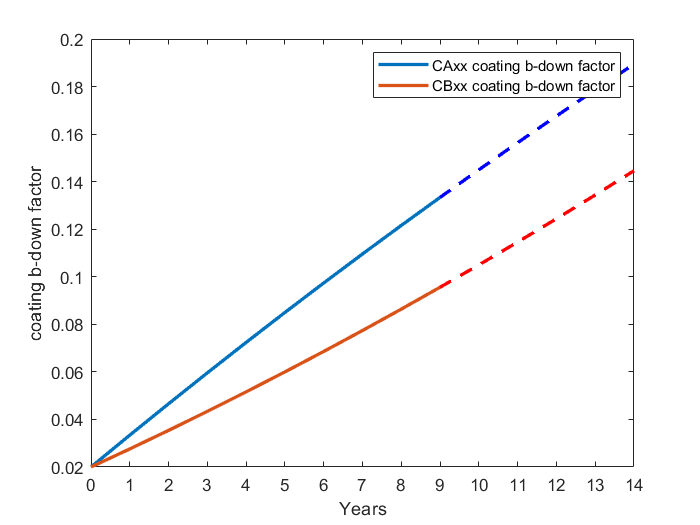

figure;

%xticklabels(strsplit(num2str(p_values_0_14(1:10,1).')));
%xticklabels(arrayfun(@num2str, p_values_0_14(1:10,1).', 'UniformOutput', 0));
%xticklabels( cellstrp_values_0_14(1:10,1).');

plot(1:10, p_values_0_14(1:10,1),'LineWidth', 2);
hold on;
plot(1:10, p_values_0_14(1:10,2),'LineWidth', 2);

plot(10:15, p_values_0_14(10:end,1),'LineWidth', 2, 'color' ,'b', 'LineStyle', '--');

plot(10:15, p_values_0_14(10:end,2),'LineWidth', 2, 'color' ,'r', 'LineStyle', '--');

%set(gca,'XAxisLocation','top');

legend( {'CAxx coating b-down factor','CBxx coating b-down factor'});

set(gca, 'Xtick', 1:15); 
set(gca, 'XTickLabel', strsplit(num2str(years)));
ylabel('coating b-down factor');
xlabel('Years');
xlim([1,15])

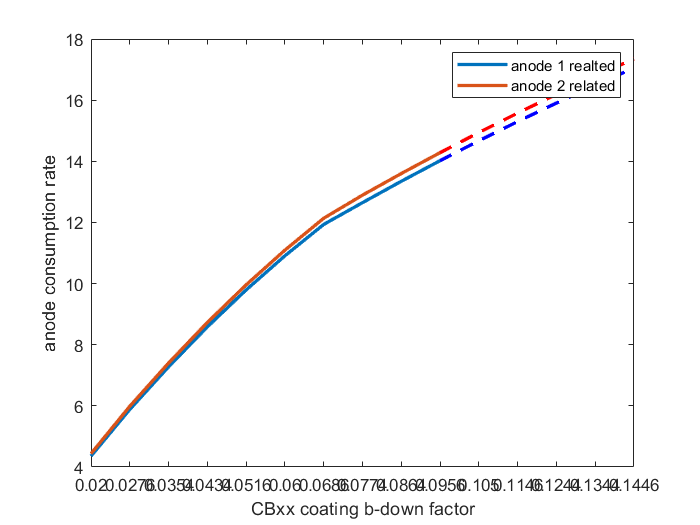

figure;

%xticklabels(strsplit(num2str(p_values_0_14(1:10,1).')));
%xticklabels(arrayfun(@num2str, p_values_0_14(1:10,1).', 'UniformOutput', 0));
%xticklabels( cellstrp_values_0_14(1:10,1).');

plot(1:10, anode1_2_consumtions_rate(1:10,1),'LineWidth', 2);
hold on;
plot(1:10, anode1_2_consumtions_rate(1:10,2),'LineWidth', 2);

plot(10:15, anode1_2_consumtions_rate(10:end,1),'LineWidth', 2, 'color' ,'b', 'LineStyle', '--');

plot(10:15, anode1_2_consumtions_rate(10:end,2),'LineWidth', 2, 'color' ,'r', 'LineStyle', '--');

%set(gca,'XAxisLocation','top');

legend( {'anode 1 realted','anode 2 related'});

set(gca, 'Xtick', 1:15); 
set(gca, 'XTickLabel', strsplit(num2str(p_values_0_14(1:15,2).')));
xlabel('CBxx coating b-down factor');
ylabel('anode consumption rate');
xlim([1,15])

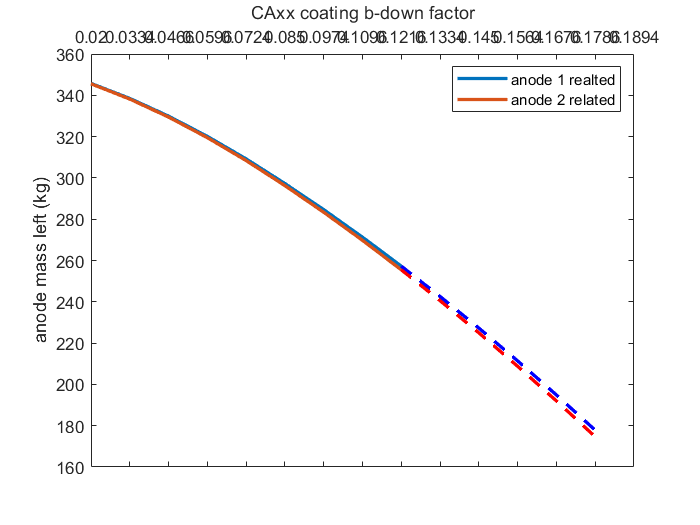

%anode_left_year_wise = zeros(15,2);

figure;

plot(years(1:10), anode_left_year_wise(1:10,1),'LineWidth', 2);

hold on;


plot(years(1:10), anode_left_year_wise(1:10,2),'LineWidth', 2);

plot(years(10:end), anode_left_year_wise(10:end,1),'LineWidth', 2, 'color' ,'b', 'LineStyle', '--');

plot(years(10:end), anode_left_year_wise(10:end,2),'LineWidth', 2, 'color' ,'r', 'LineStyle', '--');


legend({'anode 1 realted','anode 2 related'});

set(gca,'XAxisLocation','top');
set(gca, 'Xtick', 1:15); 
set(gca, 'XTickLabel', strsplit(num2str(p_values_0_14(1:15,1).')));
xlabel('CAxx coating b-down factor');
ylabel('anode mass left (kg)');
xlim([1,15])